# Datos espaciales: Análisis de datos de CTD para la identificación 

# de influencia de agua dulce en Isla Arena

### Computación y análisis de datos geofísicos

### 2026-2 

### Profesor: Dr. Ismael Mariño Tapia

### Alumna: Tut Mengual Karla Nayeli 

### Introducción

En este trabajo se realizó el procesamiento y análisis de datos oceanográficos obtenidos durante una campaña de campo en Isla Arena, donde se utilizó un CTD Diver arrastrado desde una lancha con el objetivo de identificar posibles zonas con influencia de agua dulce. Para ello los datos del CTD y del sistema de posicionamiento GPS fueron importados y procesados en MATLAB. 

Durante el análisis se llevaron a cabo diferentes etapas de tratamiento, incluyendo la revisión y limpieza de los datos crudos, la eliminación de registros no válidos, el suavizado de la señal de conductividad y la interpolación temporal para sincronizar las mediciones del CTD con las coordenadas geográficas registradas por el GPS. Finalmente, se generaron gráficas que permiten visualizar la distribución espacial de la conductividad, incluyendo una gráfica tipo *scatter* con las coordenadas X–Y y los valores de conductividad, con el fin de analizar su comportamiento a lo largo de la trayectoria de muestreo y evaluar posibles señales de influencia de agua dulce en la zona de estudio.

## **1. Importación y lectura de datos **

En esta parte del código se abre el archivo `bati_240115110238_X1819.CSV`, que contiene los datos obtenidos con el CTD Diver. Este archivo almacena las mediciones registradas por el instrumento, incluyendo fecha y hora, presión, temperatura y conductividad específica del agua.

Para poder acceder a esta información desde MATLAB se utiliza la función `fopen`, que permite abrir el archivo en modo de lectura (`'r'`). El archivo se encuentra en la ruta especificada dentro del equipo y, al abrirse, MATLAB genera un identificador de archivo (`fid1`), que funciona como referencia para poder leer posteriormente cada línea del archivo y procesar los datos contenidos en él.

El archivo generado por el CTD contiene un encabezado con información de configuración del instrumento antes de las mediciones. 

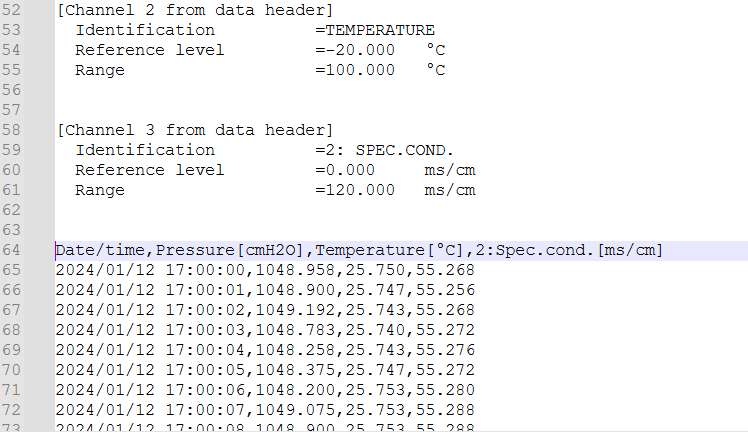

Por ello en MATLAB se utiliza un ciclo que lee las primeras 64 líneas del archivo mediante la función `fgetl, `para omitir esa información y posiciona el cursor de lectura justo en la sección donde comienzan los datos reales de fecha, presión, temperatura y conductividad que posteriormente serán procesados.

fid1 = fopen('C:\Users\karla\OneDrive\Documentos\LCT\SEMESTRE 6\COMPUTACIÓN Y ANÁLISIS DE DATOS\TAREA 3\bati_240115110238_X1819.CSV', 'r') % Abrimos el archivo

fid1 = 6

for j=1:64 
    s = fgetl(fid1) 
end

s = 'Data file for DataLogger.'

s = '=============================================================================='

s = 'COMPANY    : <Company name>'

s = 'COMP.STATUS: Do'

s = 'DATE       : 15/01/2024'

s = 'TIME       : 11:02:39'

s = 'FILENAME   : C:\Users\lapcof_fieldPC\Documents\All Work\Proyectos vigentes\IslaArena\CTDs\DiverBatim\CSV\bati_240115110238_X1819.CSV'

s = 'CREATED BY : Diver-Office 12.0.3.0'

s = '==========================    BEGINNING OF DATA     =========================='

s = '[Logger settings]'

s = '  Instrument type         =CTD-Diver=17'

s = '  Status                  =Started =0'

s = '  Serial number           =..14-X1819  317.'

s = '  Instrument number       =          UTC+0     '

s = '                          =0'

s = '  Location                =bati'

s = '  Sample period           =S01'

s = '  Sample method           =T   '

s = '  Number of channels      =3'

s = '[Channel 1]'

s = '  Identification          =PRESSURE'

s = '  Reference level         =400.000   cm'

s = '  Range                   =1750.000  cm'

s = '  Master level            =1750      CMH2O'

s = '  Altitude                =0         m'

s = '[Channel 2]'

s = '  Identification          =TEMPERATURE'

s = '  Reference level         =-20.000   °C'

s = '  Range                   =100.000   °C'


s =

  0×0 empty char array


s =

  0×0 empty char array



s = '[Channel 3]'

s = '  Identification          =2: SPEC.COND.'

s = '  Reference level         =0.000     ms/cm'

s = '  Range                   =120.000   ms/cm'


s =

  0×0 empty char array


s =

  0×0 empty char array



s = '[Series settings]'

s = '  Serial number           =..14-X1819  317.'

s = '  Instrument number       =          UTC+0     '

s = '  Location                =bati'

s = '  Sample period           =00 00:00:01 0'

s = '  Sample method           =T   '

s = '  Start date / time       =00:00:17 12/01/24'

s = '  End date / time         =10:18:21 12/01/24'

s = '[Channel 1 from data header]'

s = '  Identification          =PRESSURE'

s = '  Reference level         =400.000   cm'

s = '  Range                   =1750.000  cm'

s = '  Master level            =1750      CMH2O'

s = '  Altitude                =0         m'

s = '[Channel 2 from data header]'

s = '  Identification          =TEMPERATURE'

s = '  Reference level         =-20.000   °C'

s = '  Range                   =100.000   °C'


s =

  0×0 empty char array


s =

  0×0 empty char array



s = '[Channel 3 from data header]'

s = '  Identification          =2: SPEC.COND.'

s = '  Reference level         =0.000     ms/cm'

s = '  Range                   =120.000   ms/cm'


s =

  0×0 empty char array


s =

  0×0 empty char array



s = 'Date/time,Pressure[cmH2O],Temperature[°C],2:Spec.cond.[ms/cm]'

A partir de la línea 65 es donde comienzan las mediciones, mediante un bucle `for`, se lee cada línea del archivo con la función `fgetl`, guardándola temporalmente en la variable `currentLine`.

La función `strsplit` separa los valores de esa línea utilizando la coma como delimitador, generando un arreglo con los distintos datos registrados 

Después, cada elemento del arreglo se convierte al tipo de dato adecuado y se almacena en vectores: la fecha y hora se transforma en formato `datetime` y se guarda en `time`, la presión, temperatura y conductividad se convierten de texto a valores numéricos con `str2double` y se almacenan en los vectores `p`, `t` y `cond.`

for j=65:15555
    currentLine = fgetl(fid1);
    data = strsplit(currentLine, ','); 
    time(j)=datetime(data{1}, "InputFormat","yyyy/MM/dd HH:mm:ss"); 
    p(j)=str2double(data{2}); % Presión
    t(j)=str2double(data{3}); % Temperatura
    cond(j)=str2double(data{4}); %Conductividad
end

## 2. Visualización de datos

En esta sección genera una gráfica que muestra la variación de la conductividad y la presión registradas por el CTD a lo largo del tiempo.

Esta gráfica se realiza para visualizar cómo cambian la conductividad y la presión a lo largo del tiempo durante el recorrido. Al representar ambas variables en una serie temporal, es posible identificar variaciones en las propiedades del agua registradas durante el muestreo. Los cambios en la conductividad pueden indicar zonas con diferente salinidad, lo cual ayuda a detectar posibles influencias de agua dulce, mientras que la presión permite observar las variaciones asociadas a la profundidad o al movimiento del sensor durante el arrastre, Facilitando la interpretación del comportamiento de los datos medidos en campo.

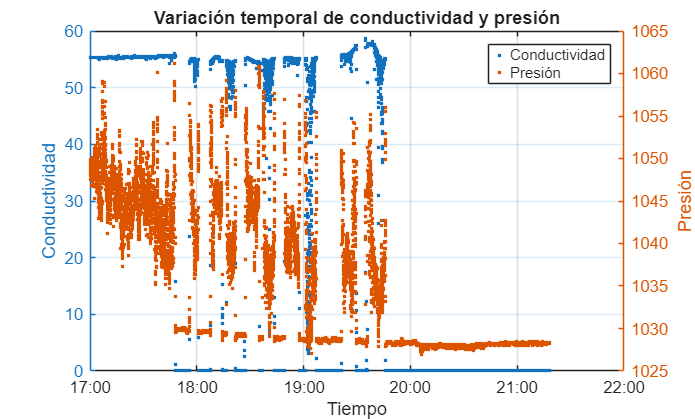

figure(1)
yyaxis ('left')
plot(time,cond,'.')
ylabel('Conductividad')
yyaxis ('right')
plot(time,p,'.')
ylabel('Presión')
xlabel('Tiempo')
legend('Conductividad','Presión')
title('Variación temporal de conductividad y presión')
legend('Conductividad','Presión')
datetick
grid on

También se realiza un `scatter `para visualizar simultáneamente la relación entre tiempo, presión y conductividad registradas por el CTD.

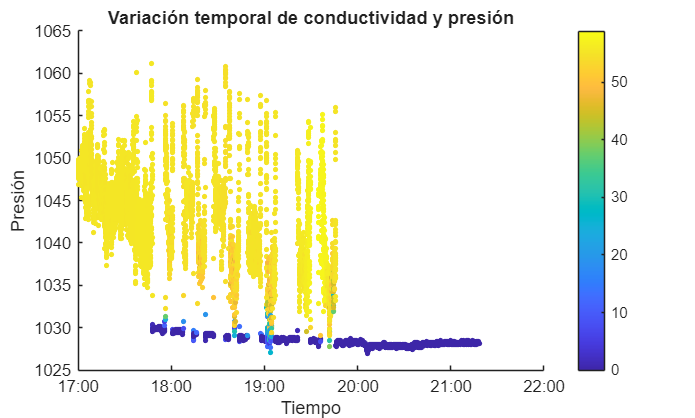

figure (2)
scatter(time,p,10,cond,'filled')
title('Variación temporal de conductividad y presión')
ylabel('Presión')
xlabel('Tiempo')
datetick
colorbar

Al analizar los gráficos se identifican varios intervalos en los que la presión se mantiene cercana a la presión atmosférica, mientras que la conductividad disminuye considerablemente o deja de registrarse, indica que durante esos momentos, el sensor no se encontraba completamente sumergido, sino que probablemente estuvo fuera del agua.

En los periodos donde la presión presenta valores mayores que la atmosférica, el sensor se encontraba dentro de la columna de agua y las mediciones son representativas. En estos segmentos se observan valores de conductividad cercanos a 55 mS/cm, típicos de agua marina, lo que indica que durante esos intervalos el instrumento estaba registrando correctamente.

Hacia el final del registro se observa un tramo en el que la conductividad deja de presentar valores, mientras que la presión permanece casi constante y cercana a la atmosférica, aquí el instrumento ya no se encontraba sumergido ni realizando mediciones útiles.

A partir de estas observaciones, es necesario aplicar un proceso de limpieza de datos, eliminando los intervalos en los que la presión es cercana a la atmosférica, ya que corresponden a mediciones realizadas fuera del agua y no aportan información útil para el análisis de las propiedades del sistema.

Se realiza un tercer gráfico en donde sólo se grafica la conductividad, para observar más a detalle la distribución de los datos, la mayor parte de los valores se mantienen alrededor de 54–56, igual se observan descensos bruscos de la conductividad e incluso valores cercanos a cero en algunos intervalos, lo que muestra que el sensor probablemente salió del agua o registró datos no válidos.

figure(3)
plot(time,cond,'.r')
xlabel('Tiempo')
ylabel('Conductividad')
title('Variación temporal de la conductividad')
datetick
grid on

## 3. Acotar el tiempo. 

De manera manual definir en la grafica 3 el rango en donde se cuentran los datos representativos, y descartarel intervalo al final del registro, donde se observan momentos en los que el instrumento probablemente no estaba aún dentro del agua o ya había sido extraído.

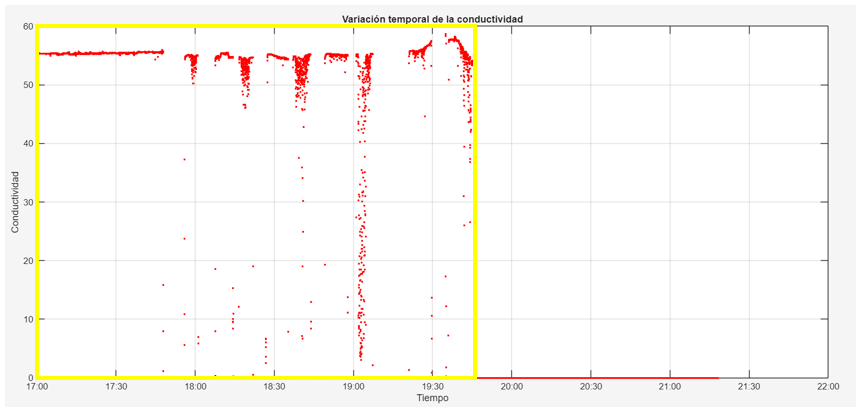

El procedimiento consiste en seleccionar y extraer un rango específico de datos directamente desde la gráfica. Para ello, primero se coloca el cursor sobre la línea o los puntos de la gráfica que contienen la información de interés. Después, se realiza clic derecho sobre el punto o la zona deseada, lo que abre un menú de opciones. En este menú se selecciona la opción “Export Data All”, mediante un clic izquierdo, lo que permite exportar los datos mostrados en la gráfica al espacio de trabajo. De esta manera es prosible trabajar únicamente con el intervalo de datos seleccionado, y se delimita del rango que se desea analizar.

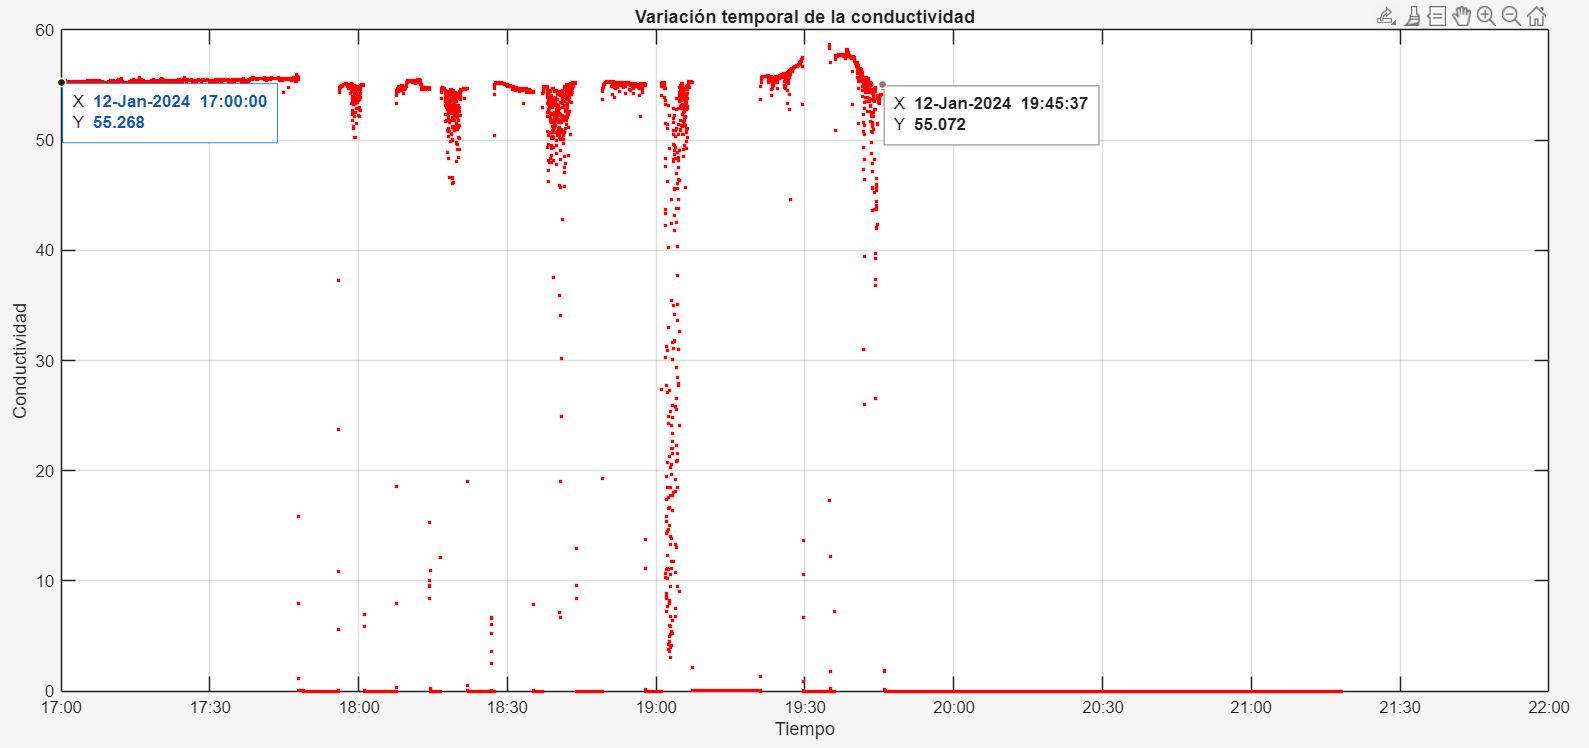

Se extrae únicamente el rango de datos que fue seleccionado previamente en la gráfica. Se utilizan las posiciones de inicio y fin obtenidas a partir del cursor (`cursor_inicio` y `cursor_fin`) en el campo `DataIndex, `que indica el número de posición del dato seleccionado dentro del arreglo original. que indica la posición del punto seleccionado dentro de los vectores originales.

A partir de esos índices se crea un subconjunto de datos. En `cond2` se guardan los valores de conductividad comprendidos entre el punto inicial y el punto final seleccionado. De la misma manera, `time2` almacena el intervalo correspondiente de tiempo, y `p2` guarda los valores de presión para ese mismo rango. De esta forma se obtienen nuevos vectores que contienen solo los datos del segmento de interés, lo que facilita continuar con el análisis utilizando únicamente las mediciones válidas.

cond2 = cond(cursor_inicio.DataIndex:cursor_fin.DataIndex);
time2 = time(cursor_inicio.DataIndex:cursor_fin.DataIndex);
p2 = p(cursor_inicio.DataIndex:cursor_fin.DataIndex);

Sobre la grafica 3 se resalta el subconjunto de datos seleccionado, esto permite visualizarlos después del proceso de selección o limpieza, eliminando los segmentos donde el sensor no estaba sumergido. De esta forma, se obtiene una representación más clara y confiable del comportamiento real de la conductividad durante el muestreo.

hold on
plot(time2,cond2,'.b')
ylabel('Conductividad')
xlabel('Tiempo')
title('Variación temporal acotada de la conductividad')
datetick
grid on

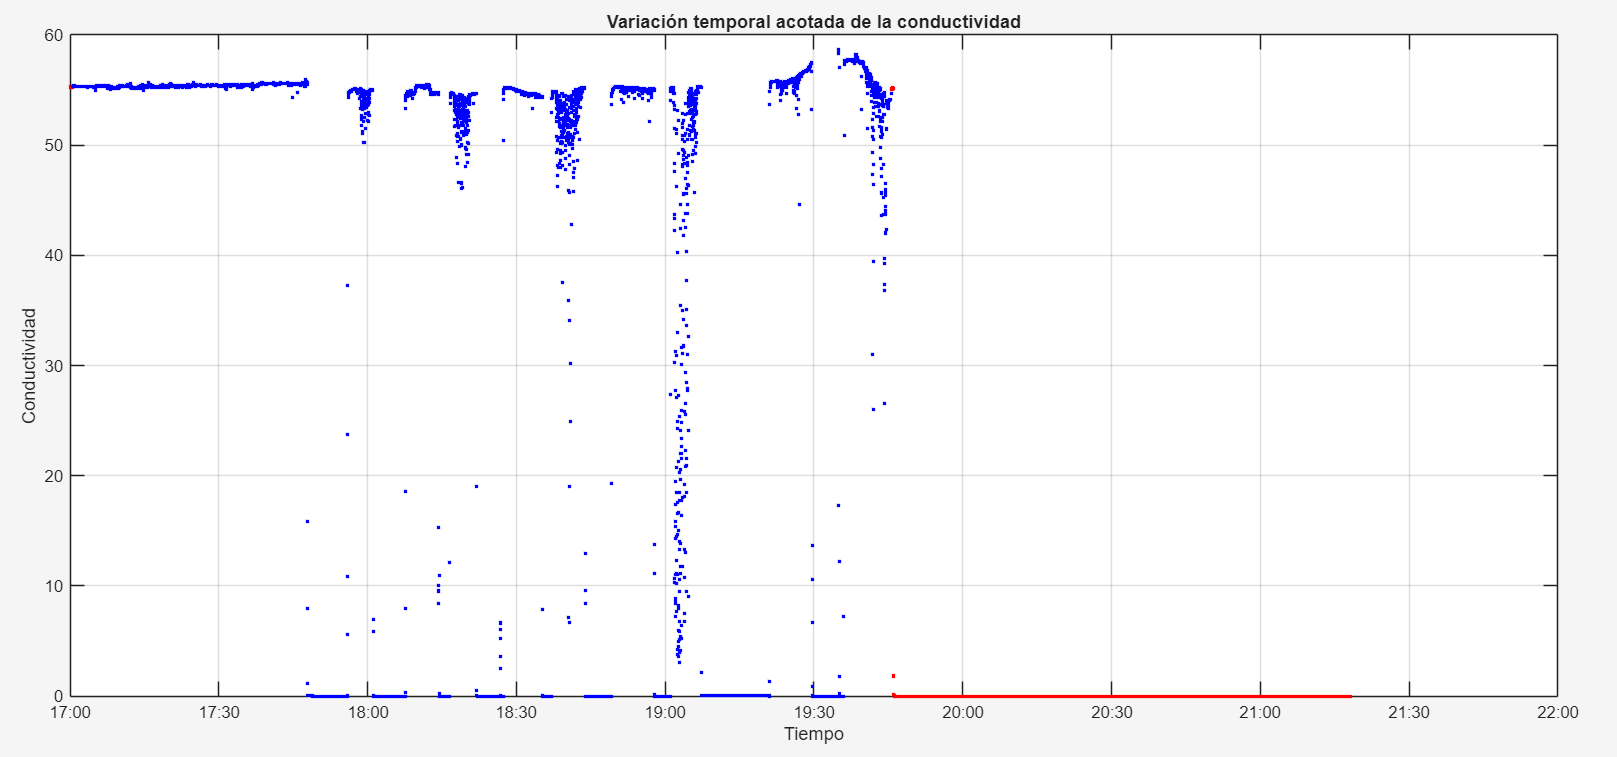

Los puntos azules corresponden al rango de datos seleccionado. En este intervalo la conductividad se mantiene mayormente entre 50 y 56 mS/cm, valores típicos de agua marina, lo que indica que el sensor se encontraba sumergido. Aunque aparecen algunos descensos puntuales, la mayoría de los datos se concentra en un rango coherente y estable, por lo que este subconjunto puede considerarse adecuado para continuar con el análisis.

## 4. Limpieza de datos sumergidos

Para mejorar el proceso de limpieza de los datos, se selecionan únicamente las mediciones que cumplen con un criterio específico de presión. Primero, `s = find(p2 > 1040) `identifica las posiciones donde la presión es mayor a 1040, lo que indica que el sensor se encontraba sumergido en la columna de agua y no expuesto al aire. Posteriormente, esas posiciones se utilizan como índice para extraer los valores correspondientes de conductividad, tiempo y presión, generando los nuevos vectores `cond3`, `time3` y `p3`. Así se obtiene un conjunto de datos más confiable, eliminando registros asociados a presiones cercanas a la atmosférica que podrían corresponder a mediciones fuera del agua.

%criterio mas cuantitativo escogiendo solo los datos sumergidos utilizando un sensor en el umbral de presión.
s = find(p2 > 1040);
cond3 = cond2(s);
time3 = time2(s);
p3    = p2(s);

Se realiza una gráfica para verificar visualmente que el procedimiento de filtrado funcionó correctamente, eliminando los valores asociados a mediciones fuera del agua o con comportamiento anómalo. De esta manera se confirma que el conjunto final de datos es  adecuado para continuar con el análisis.

hold on
plot(time3,cond3,'.k')
grid on

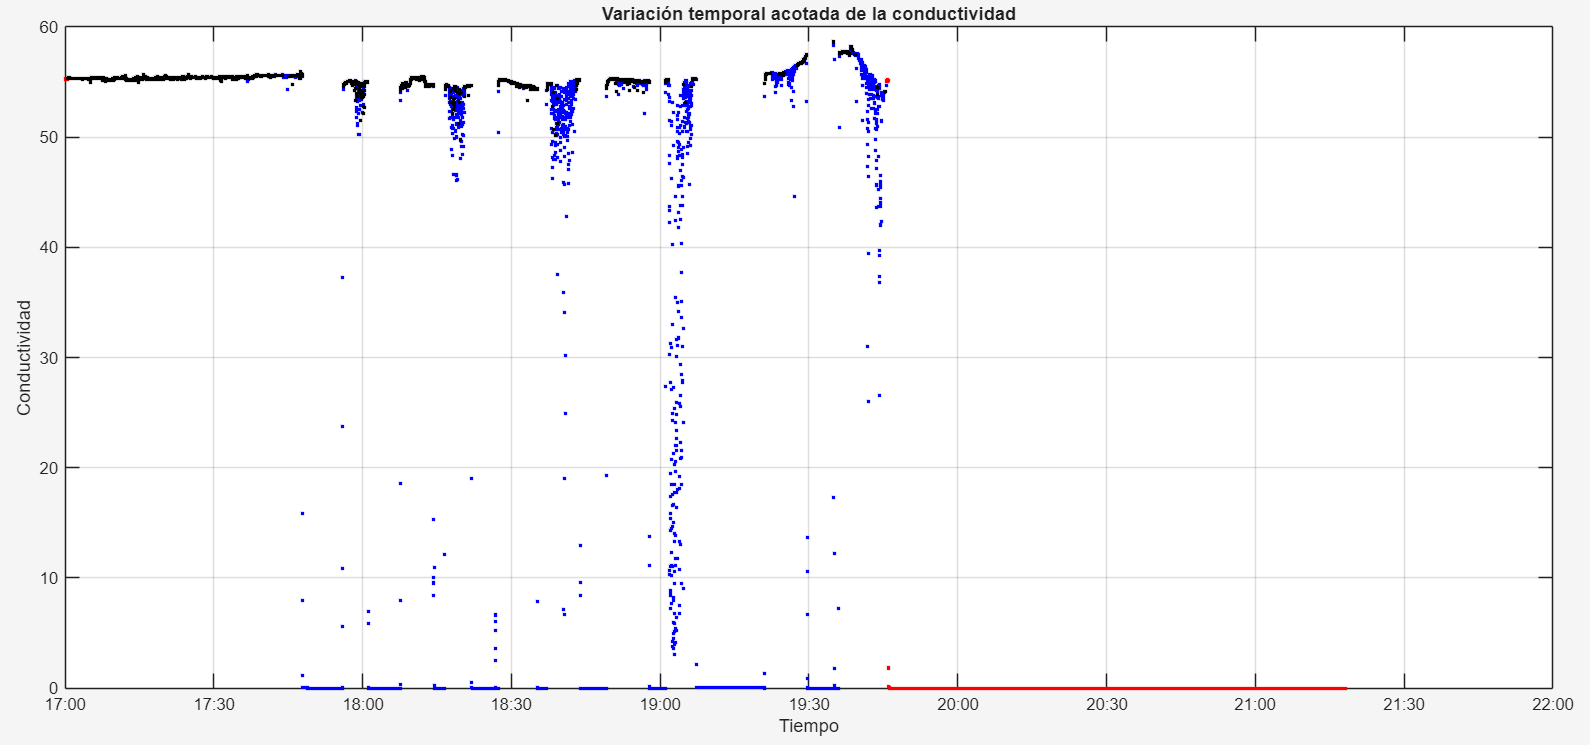

Esta la gráfica se visualizan los datos originales seleccionados (azul) con los datos filtrados después de aplicar el criterio de presión (negro). Los puntos negros representan únicamente las mediciones en las que la presión indica que el sensor estaba realmente sumergido, por lo que corresponden a datos más confiables para el análisis.

Para reducir el ruido presente en los datos de conductividad, se aplicó un proceso de suavizado utilizando un filtro de media móvil mediante la función `smoothdata`.

En el código `cond4 = smoothdata(cond3,'movmean',60);`, la opción `'movmean'` indica que se calculará un promedio móvil, mientras que el valor 60 corresponde al tamaño de la ventana de suavizado. Se promedian 60 datos consecutivos, equivalente  a 60 segundos (1 minuto) del registro. Esto permite suavizar la señal facilita la identificación de tendencias más claras en la conductividad.

cond4 = smoothdata(cond3,'movmean',60);
%Gráfica de los datos suavizados 
hold on
plot(time3,cond4,'.m')
legend('Datos acotados (en tiempo y presión)','Datos suavizados')
datetick

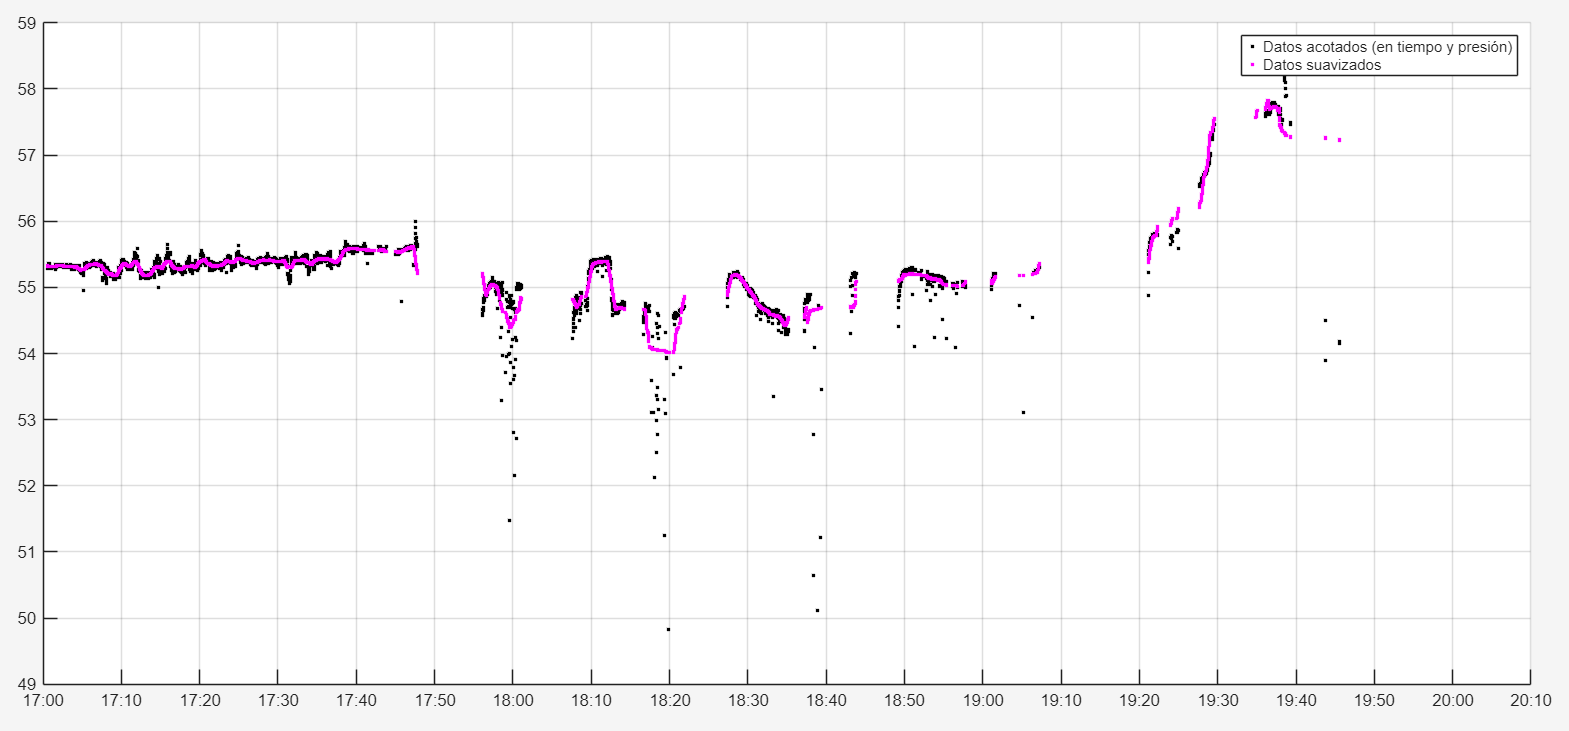

Desde la sección del gráfico, en la pestaña *Format *se selecciona la opción *Select and Plort Edit *y con el click derecho eliminamos los datos acotados en tiempo y presión, para tener una mejor visualización de los datos suavizados (media móvil)

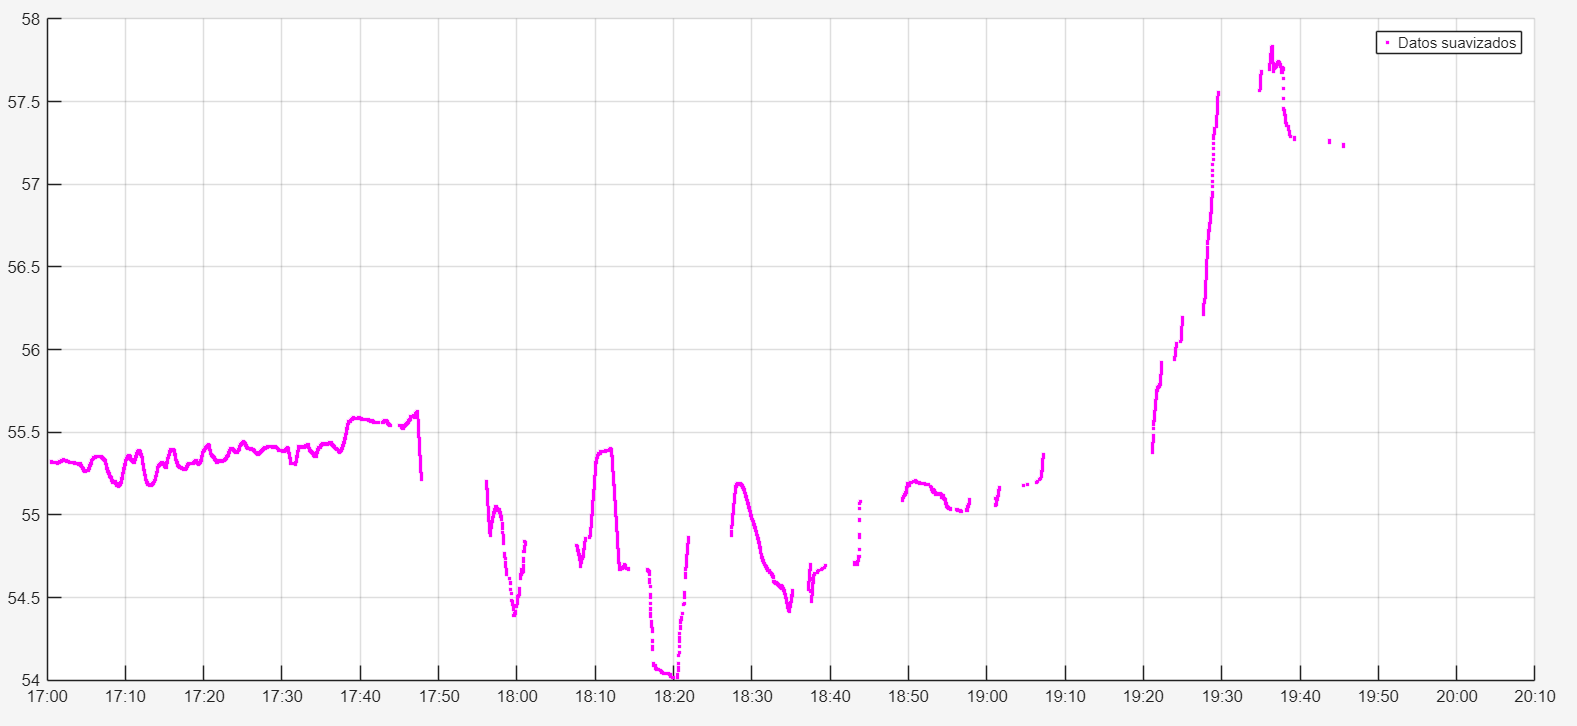

La curva suavizada muestra que la conductividad se mantiene alrededor de 55–55.5 mS/cm durante la primera parte del registro, lo que es consistente con condiciones de agua marina. Posteriormente se observan pequeñas disminuciones entre 54 y 55 mS/cm, que podrían reflejar cambios locales en la masa de agua o variaciones en la mezcla. Hacia la parte final del intervalo se aprecia un incremento progresivo de la conductividad, alcanzando valores cercanos a 57–57.5 mS/cm. El suavizado permite observar con mayor claridad la tendencia general de la conductividad a lo largo del tiempo, reduciendo el ruido presente en los datos originales.

## 5. Interpolación lineal simple

En la gráfica de los datos suavizados se observa que hay espacios vacíos entre la secuencia de datos, para rellenar estos segmentos se realiza una interpolación.

Se utiliza la función `interp1 `para calcular valores en los intervalos donde no hay mediciones, utilizando como referencia los datos suavizados (`cond4`). Se aplican dos métodos de interpolación: lineal y pchip, siendo este último el que genera una curva más suave y realista.

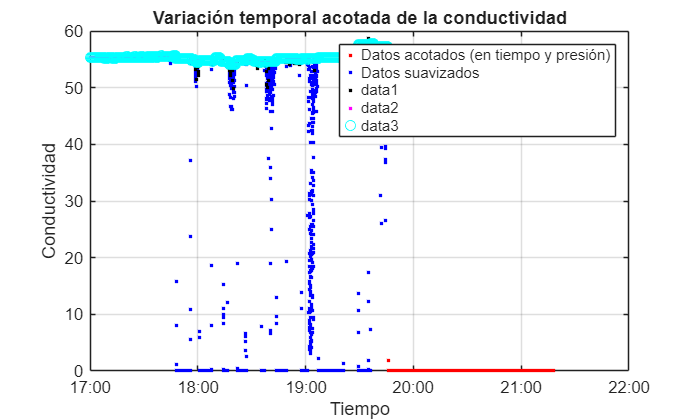

plot(time3,cond3,'.k')
grid on
cond5 = interp1(time3,cond4,time2); 
cond6 = interp1(time3,cond4,time2,'pchip');%Interpolacion cubica
hold on
plot(time3,cond4,'.m')
plot(time2,cond6,'oc')
ylabel('Conductividad')
xlabel('Tiempo')

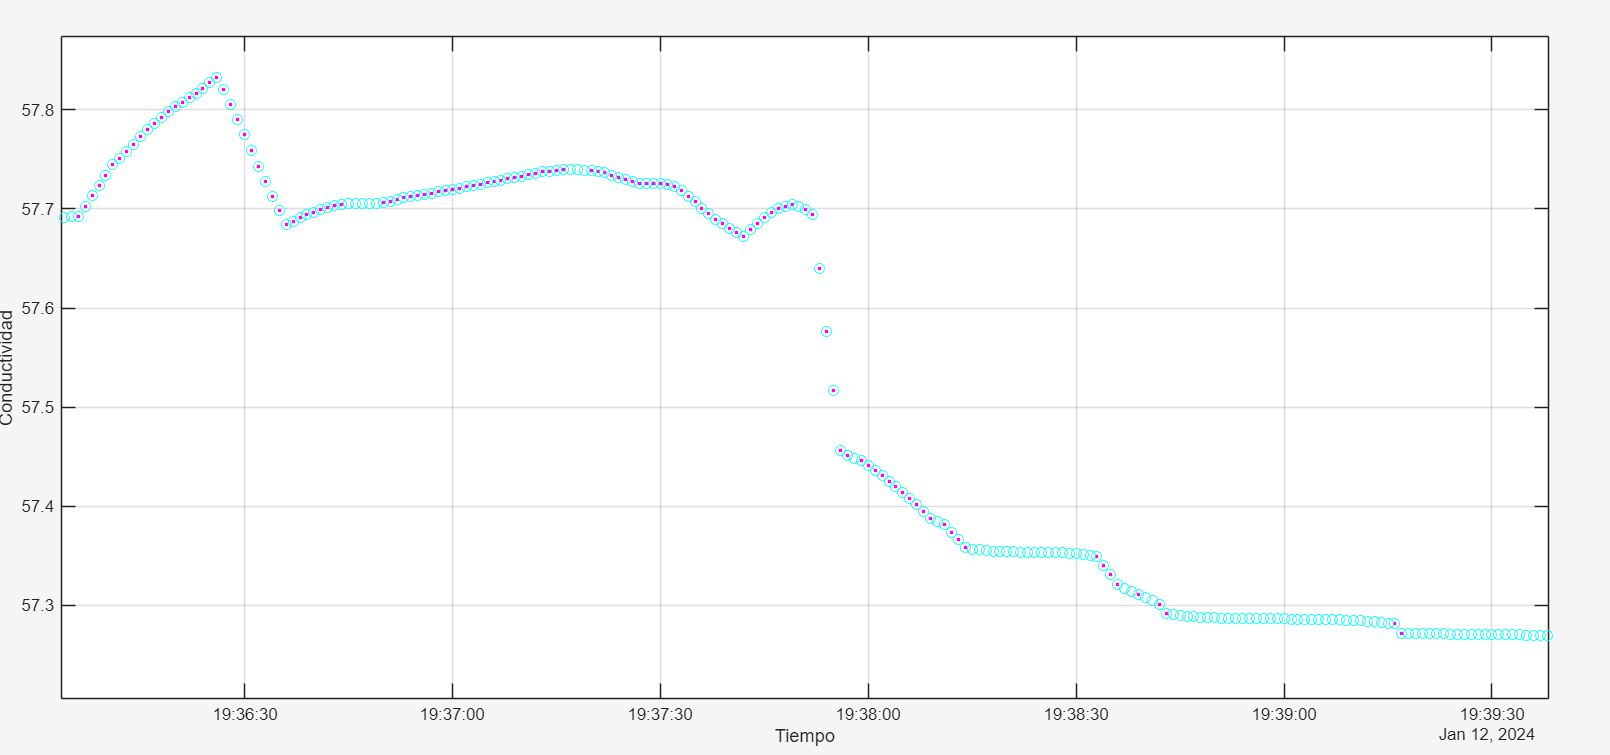

En la gráfica, los segmentos donde no aparecen puntos rosados y se observa una línea formada por círculos de color cian corresponden a los valores estimados mediante interpolación, los cuales se utilizan para completar los intervalos donde no existían datos originales. De esta manera, la interpolación permite reconstruir de forma continua la serie temporal de conductividad en los espacios donde el registro presentaba vacíos.

## 6. Extracción de datos de GPS 

Para complementar el análisis de los datos obtenidos con el CTD, también se incorporaron al espacio de trabajo de MATLAB los datos de GPS contenidos en el archivo `Track2.csv`, el cual almacena la información de la trayectoria seguida durante el muestreo. 

Este archivo incluye las posiciones geográficas registradas a lo largo del recorrido, lo que permite ubicar espacialmente los puntos donde se realizaron las mediciones. Al importar estos datos en MATLAB, es posible organizarlos y prepararlos para su posterior procesamiento, con el fin de relacionar la información de posición con las variables medidas por el CTD y así analizar la distribución espacial de las observaciones.

En una inspección de la estructura se observa que tenemos datos de interes desde la línea 1

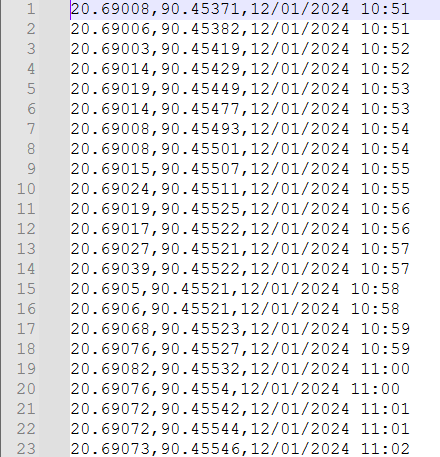

Para leer y organizar los datos de GPS almacenados en el archivo `Track2.csv`. Primero, con `fopen` se abre el archivo en modo de lectura y se inicia un ciclo `for` que recorre las 385 filas del archivo. En cada iteración, `fgetl` lee una línea del archivo y `strsplit` separa los valores usando la coma como delimitador.

Se extraen y convierten los datos de la latitud y la longitud, y se transforman a valores numéricos con `str2double`, mientras que la fecha y hora se convierten al formato `datetime`.

fid2 = fopen('C:\Users\karla\OneDrive\Documentos\LCT\SEMESTRE 6\COMPUTACIÓN Y ANÁLISIS DE DATOS\TAREA 3\Track2.csv','r');
for j = 1:385   
    s2 = fgetl(fid2);  
    data2 = strsplit(s2,','); 
    Lat(j)  = str2double(data2{1});
    Lon(j)  = -str2double(data2{2});
    tGPS(j) = datetime(data2{3},'InputFormat','dd/MM/yyyy HH:mm');    
end
fclose(fid2);

Se eliminan los tiempos repetidos del GPS para evitar que existan varios registros de posición asociados al mismo instante debido a que genera inconsistencias. Primero se convierte el tiempo del GPS a un formato numérico, lo que facilita su manejo en MATLAB. Luego se identifican los instantes de tiempo únicos y se conservan únicamente las latitudes y longitudes correspondientes a esos registros, obteniendo así un conjunto de datos de posición sin duplicados.

% Convertir tiempo del GPS a formato numérico
tiempo_gps = datenum(tGPS);

% Obtener tiempos únicos del GPS
[tiempo_gps_unico, idx_pos] = unique(tiempo_gps);

% Coordenadas correspondientes a esos tiempos
lat_validas = Lat(idx_pos);
lon_validas = Lon(idx_pos);

A partir de la información mostrada en la configuración del instrumento, se observa que el CTD registra el tiempo en formato UTC (Tiempo Universal Coordinado), las mediciones de tiempo del CTD están referidas a la zona horaria UTC+0, por lo que es necesario considerar este aspecto al comparar o sincronizar estos datos con los del GPS, que pueden estar almacenados en una zona horaria local diferente.

Se ajusta el tiempo de las mediciones del CTD con los datos del GPS. La función `datevec` descompone el tiempo almacenado en `time2` (año, mes, día, hora, minuto y segundo). Mediante `datetime` se crea un objeto de fecha y hora indicando que esos valores corresponden a UTC, que es la referencia temporal utilizada por el CTD.

Ese tiempo se convierte a la zona horaria local de México (`America/Mexico_City`), de manera que coincida con el horario de los datos registrados por el GPS, luego se transforma el tiempo a un formato numérico con `datenum.`

% Manejo del tiempo del CTD
componentes_fecha = datevec(time2); % separar la fecha en componentes
tiempo_referencia = datetime(componentes_fecha,'TimeZone','UTC'); % CTD en UTC
hora_mexico = datetime(tiempo_referencia,'TimeZone','America/Mexico_City'); % convertir a hora local

% Convertir a formato numérico para interpolar
tiempo_interp = datenum(hora_mexico);

Mediante una interpolación temporal, se calcula las coordenadas geográficas correspondientes a cada medición del CTD. Se utilizan los tiempos únicos del GPS junto con sus latitudes y longitudes, lo que permite estimar la posición aproximada del instrumento en cada instante de registro y así relacionar las mediciones del CTD con su ubicación espacial.

% Interpolar posición del GPS al tiempo del CTD
lat_ctd = interp1(tiempo_gps_unico, lat_validas, tiempo_interp);
lon_ctd = interp1(tiempo_gps_unico, lon_validas, tiempo_interp);

## 7. Graficar datos del GPS

Se realizan gráficas para visualizar la distribución espacial de la conductividad registrada por el CTD a lo largo del recorrido de muestreo. Para poder generar esta representación fue necesario primero procesar y limpiar los datos del CTD, eliminando registros no válidos y suavizando la señal de conductividad. 

Posteriormente, los datos de posición del GPS fueron incorporados y ajustados temporalmente, considerando las diferencias de zona horaria entre ambos instrumentos. También se eliminaron tiempos repetidos del GPS y se realizó una interpolación temporal, lo que permitió estimar la latitud y longitud correspondientes a cada medición del CTD.

Una vez asociadas las coordenadas geográficas a los datos de conductividad, se generan dos representaciones gráficas. La primera es un diagrama de dispersión en coordenadas cartesianas, que muestra la trayectoria del muestreo y cómo varía la conductividad a lo largo de ella. La segunda utiliza `geoscatter`, que proyecta los datos sobre un mapa geográfico satelital, permitiendo visualizar de manera más clara la ubicación real de las mediciones y la distribución espacial de la conductividad en la zona de estudio.

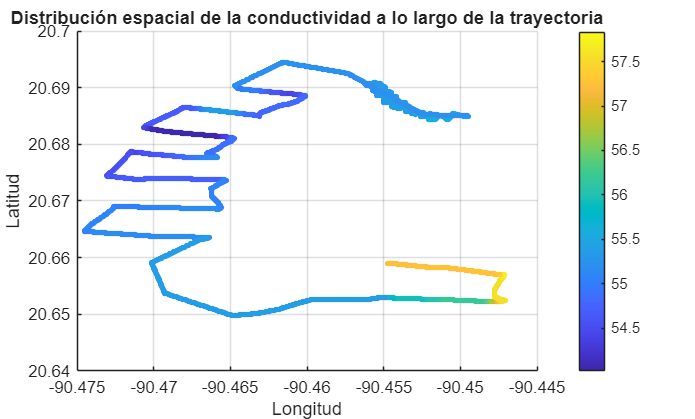

figure
scatter(lon_ctd, lat_ctd, 10, cond6, 'filled')
colorbar
xlabel('Longitud')
ylabel('Latitud')
title('Distribución espacial de la conductividad a lo largo de la trayectoria')
grid on

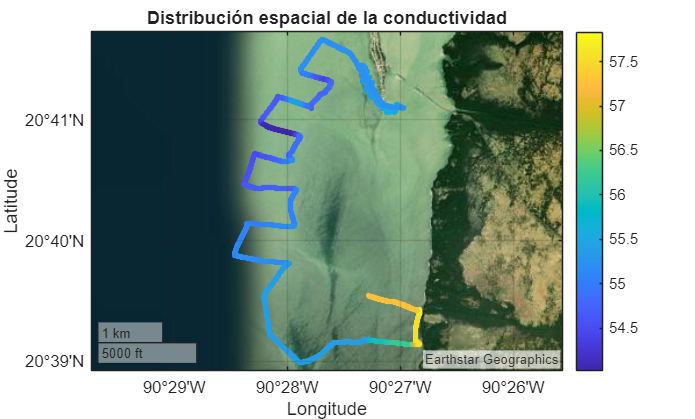


figure
geoscatter(lat_ctd, lon_ctd, 10, cond6, 'filled')
geobasemap satellite
colorbar
title('Distribución espacial de la conductividad')

La gráfica obtenida con `geoscatter `muestra la distribución espacial de la conductividad registrada por el CTD a lo largo de la trayectoria de muestreo en Isla Arena. La mayor parte del recorrido presenta valores de conductividad entre aproximadamente 54 y 56 mS/cm, característicos de agua marina, lo que indica condiciones predominantemente salinas en la zona de estudio. Sin embargo, hacia el sector cercano a la costa se observan valores ligeramente más altos de conductividad, representados con colores más cálidos, lo que podría estar asociado a cambios locales en las condiciones del agua o a variaciones en la mezcla entre masas de agua. La trayectoria del muestreo permite observar cómo estas variaciones se distribuyen espacialmente a lo largo del recorrido, facilitando la identificación de posibles zonas donde las propiedades del agua cambian.

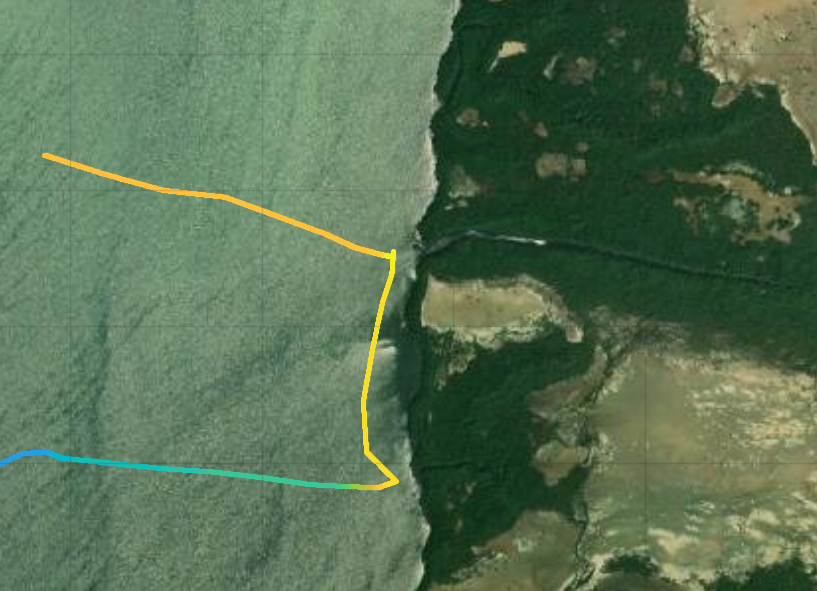 

El aumento de conductividad observado en la figura se localiza cerca de un canal que conecta el sistema lagunar con el mar, situado aproximadamente en 20°39′25″ N y 90°27′04″ W. Estas coordenadas corresponden a canales estuarinos del sistema lagunar de Isla Arena, en la costa norte de Campeche, donde los manglares y las lagunas costeras se comunican con el Golfo de México.

El patrón de incremento de salinidad que se observa en el gráfico no sigue el comportamiento típico de un estuario clásico, en el cual el aporte de agua dulce reduce la salinidad cerca de la costa. Por el contrario, en la zona de Isla Arena este comportamiento es característico de ambientes someros con tendencia evaporítica. En esta región del Golfo de México, la batimetría extremadamente somera de la plataforma de Yucatán, junto con la protección que brinda la barrera costera de Isla Arena, genera condiciones de confinamiento hidrodinámico.

A esto se suman altos niveles de radiación solar y temperaturas elevadas, que favorecen una intensa evaporación del agua en la franja litoral. Como consecuencia, el agua se evapora mientras las sales permanecen, produciendo una concentración local de salinidad. Este proceso origina un gradiente horizontal inverso, donde los valores de salinidad son más altos cerca de la costa y disminuyen gradualmente hacia mar abierto, donde la circulación oceánica permite una mayor mezcla y dilución. Además, la ausencia de aportes significativos de agua dulce superficial limita la dilución de la salinidad.

El agua marina penetra hacia el interior del canal, sobre todo cuando el aporte de agua dulce es reducido, lo que puede generar valores elevados de conductividad o salinidad cerca de la desembocadura. Entonces los máximos de salinidad son observados en la boca del estuario e indica que el sistema puede comportarse como un estuario inverso o negativo, caracterizado por una mayor salinidad en la zona costera que en el mar adyacente.

**Conclusión**

El procesamiento de los datos es importante para garantizar un análisis confiable de las mediciones obtenidas con el CTD. A través de etapas como la revisión de los datos crudos, la eliminación de registros no válidos, el suavizado de la señal y la sincronización temporal con los datos del GPS, fue posible depurar la información y obtener un conjunto de datos representativos. Con la interpolación se pudo asignar una posición geográfica a cada medición de conductividad y con ella realizar un análisis espacial. Este tratamiento de datos es necesario para evitar interpretar valores erróneos y permite identificar correctamente las variaciones en la conductividad del agua, lo que a su vez ayuda a reconocer posibles zonas con influencia de agua dulce o cambios en las propiedades del agua a lo largo del área de estudio. El análisis mostró un aumento de conductividad hacia la zona costera se deduce a que esto se debe a las condiciones someras y de alta evaporación en el sistema lagunar de Isla Arena.